%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)
% clear all
% close all 
% clc


## Part 1: Understanding Saturation and Butterworth Filter

### 1.1. understand the characteristics of F(q)

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1')

F = struct with fields:
      num: [0.5050 1.0100 0.5050]
    denom: [1 0.7478 0.2722]
      sys: [1×1 tf]


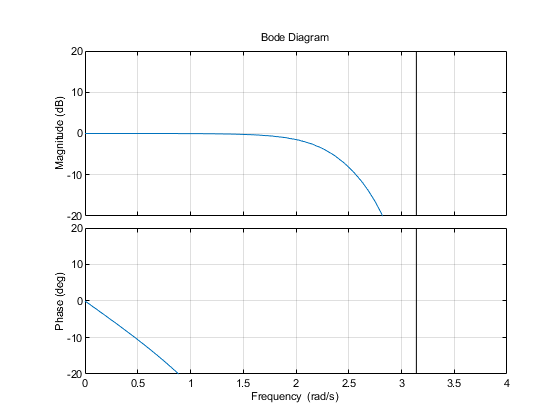


plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% w = 2.195 rad/s is the -3 db point, f = w/2/pi


### 1.2. determine M

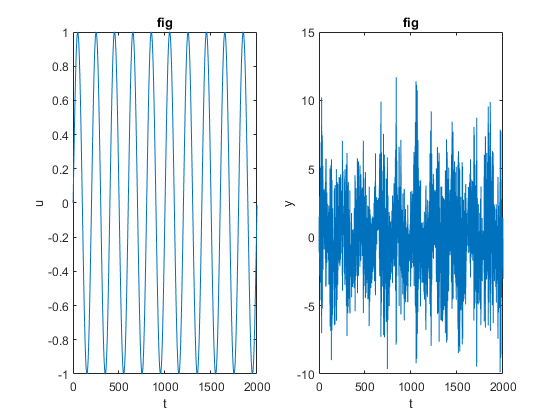

% nu = 100;
% previous_u = -100; 
% for mag=0:1:100
%     r = mag * ones(1,nu);
%     [u,y] = assignment_sys_36(r);
%     u(1)
%     previous_u
%     if (u(1) == previous_u)
%         fprintf("M is equal to %d", u(1));
%         break;
%     end
%     previous_u = u(1);
% end
% 
% % M is equal to 3

N = 2000;
f = 10;
offset = 0;
A = 1;

t = (0 : 1/N : 1)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1, 2, 1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1, 2, 2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");


% we now can know M is 3



## Part 2: Nonparametric identification

### 2.1. preliminary experiment and apply nonparametric system identification

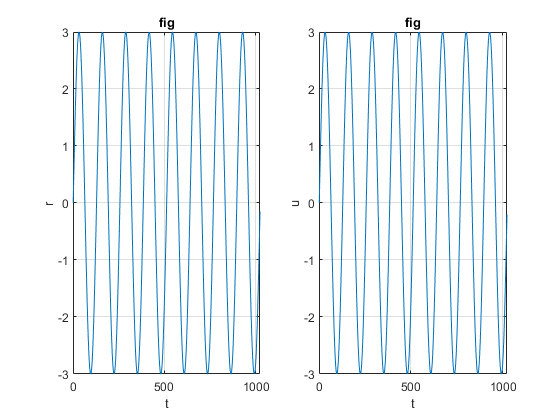

% period = 128;
% N = 1024;
% r = 3*sin( [0: 1: N-1] * pi / period )

% system setup
N = 1024;
Ts = 1;
n_freq = 128;
A = 3;

f = [0: 1: N-1]/n_freq/Ts;
r = A * sin(2*pi*f) + offset;

figure;
subplot(1, 2, 1)
plot(r)
grid on
xlabel("t"); ylabel("r"); title("fig");

[u,y] = assignment_sys_36(r);
subplot(1, 2, 2)
plot(u)
grid on
xlabel("t"); ylabel("u"); title("fig");


figure;
G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


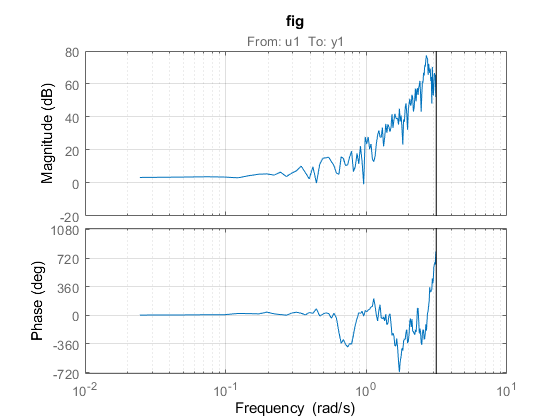

bode(G_ETFE)
grid on
title("fig");

### 2.3. estimating the noise spectrum Φv

period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


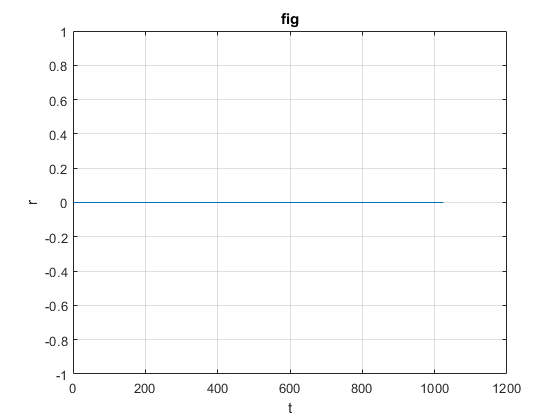

% r = 0 * sin(2*pi*f) + offset

figure;
plot(r)
grid on
xlabel("t"); ylabel("r"); title("fig");

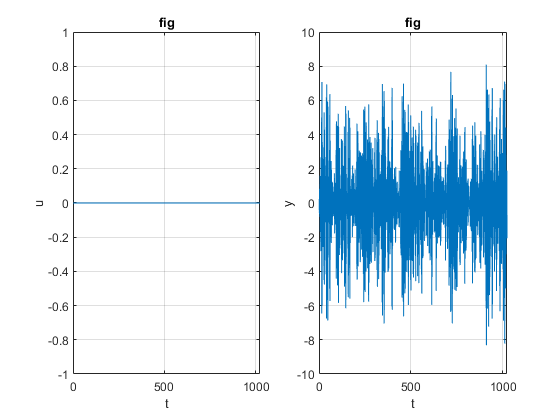


figure;
subplot(1, 2, 1)
[u,y] = assignment_sys_36(r);
plot(u)
grid on
xlabel("t"); ylabel("u"); title("fig");

subplot(1, 2, 2)
plot(y)
grid on
xlabel("t"); ylabel("y"); title("fig");

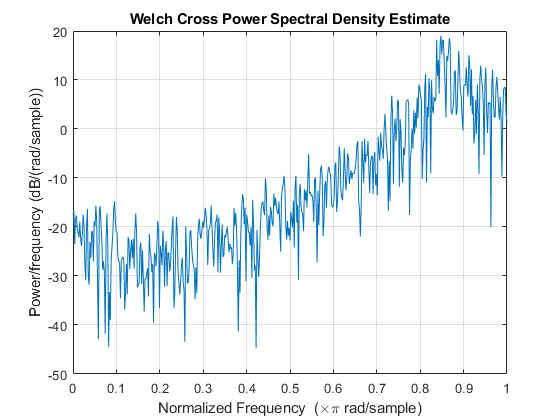


figure;
[Pv, W] = cpsd(y, y, 1024);
cpsd(y, y, 1024)

cov(y)

ans = 8.5414

## Part 3: Expreiment Design

### 3.1. Choose input signal format

% prefer PRBS




### 3.2. Design the external input signal r

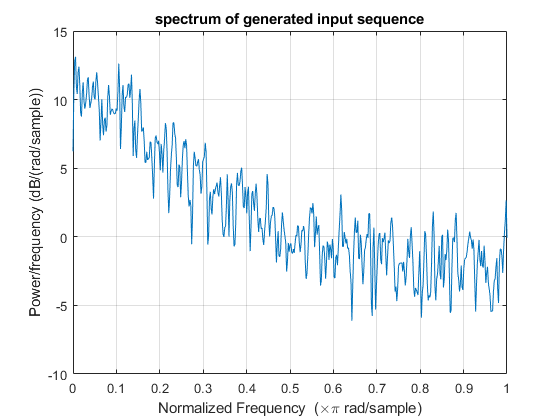

[r,P,w] = Generate_PRBS(0.83, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1. decide model structure and model orders

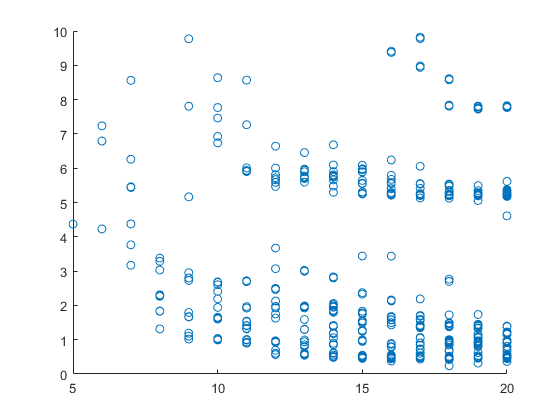

% Try OE Model

% divide the dataset into training set and validation set
[u,y] = assignment_sys_36(r);
train_ratio = 0.7;
u_train = u([1: floor(train_ratio * length(u))]);
y_train = y([1: floor(train_ratio * length(y))]);
u_test = u([floor(train_ratio * length(u))+1: end]);
y_test = y([floor(train_ratio * length(y))+1: end]);

% prepare loop for order selection
order_upper = 20;
nb = 0;
nf = 0;
nk = 0;

OE.order.order_points = [];
OE.order.order_config = [];
OE.order.error = [];

for order_sum = 1: 1: order_upper
    
    for nb = 0: 1: order_sum
        
        for nf = 0: 1: order_sum - nb
            
            nk = order_sum - nb - nf;
            % for OE model, nk and nb cannot be zero at the same time
            if nk == 0 && nb == 0
                continue;
            end
            
            % identify a model
            temp_sys = oe(iddata(y_train, u_train), [nb, nf, nk]);
            % cost validate error
            temp_predict_error = pe(temp_sys, iddata(y_test, u_test), 1);
            temp_error = abs(8.5415-temp_predict_error.y' * temp_predict_error.y / length(y_test));
            
            % abort too abnormal result
            if temp_error > 10
                continue;
            end
            
            OE.order.order_points = [OE.order.order_points, order_sum];
            OE.order.order_config = [OE.order.order_config, [nb; nf; nk]];
            OE.order.error = [OE.order.error, temp_error];
            
        end
                  
    end
end
scatter(OE.order.order_points, OE.order.error);

[M, I] = min(OE.order.error);

M = 0.2415

I = 289

OE.model_configuration = OE.order.order_config(:, I);
OE.model_order = OE.order.order_points(I);


OE.model_configuration

ans =      4
    13
     1


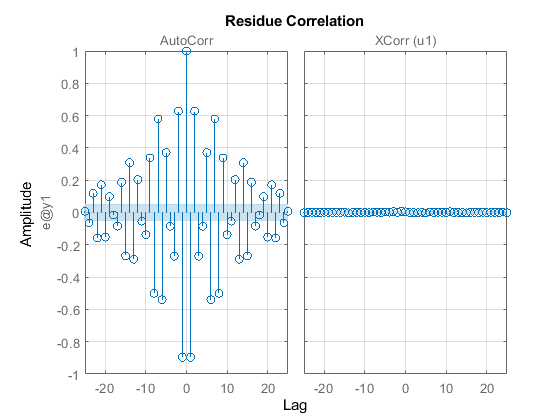


% OE.sys = oe(iddata(y_train, u_train), OE.model_configuration');
OE.sys = oe(iddata(y_train, u_train), [4,13,1]);

OE.resid = resid(iddata(y_train,u_train), OE.sys);
figure
resid(iddata(y,u), OE.sys)
grid on;

## Part 5: Experimental verification of variance estimates

### 5.1

% order A 10 order B 10 100 * 20


### 5.2

### 5.3

variance_theoretical = getcov(SYS, 'value');


### 5.4

## Part 6: Estimation of a Box Jenkins model for minimum variance

### 6.1

nb = 4;
nf = 13;
nc = 1;
nd = 5;
nk = 1;

BJ.sys = bj(iddata(y,u), [nb, nc, nd, nf, nk]);


## Function Used

function [r,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% r(t) = r(t-1) with probability p
%% r(t) = -r(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    r : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        r(1) = mag;
    else
        r(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            r(i) = r(i-1);
        else
            r(i) = -r(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(r, r, N);
    
    if (plt_flag == true)
        cpsd(r, r);
        title('spectrum of generated input sequence')
    end
    
end